# Problem 2-1

k_1 = 200 kN/m, k_2 = 250 kN/m, P = 10 kN

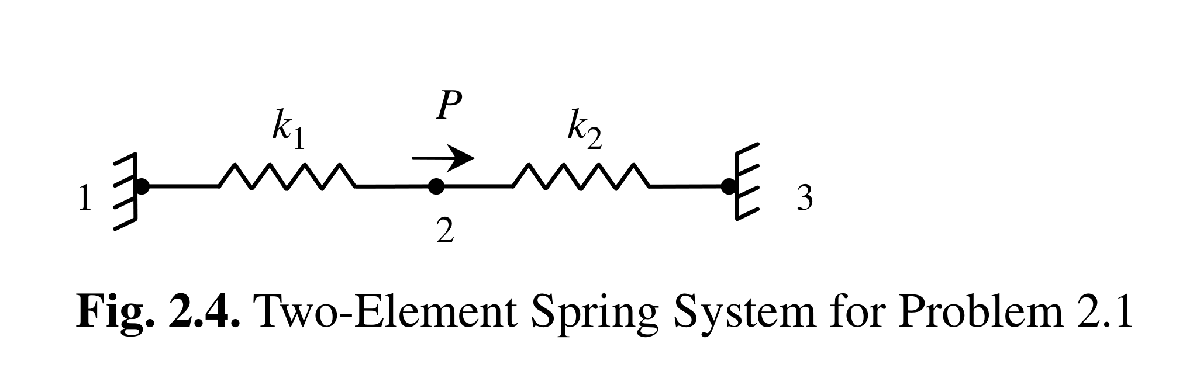

ElemConn = [1, 2; 2, 3]

ElemConn =      1     2
     2     3


k1 = SpringElementStiffness(200)

k1 =    200  -200
  -200   200


k2 = SpringElementStiffness(250)

k2 =    250  -250
  -250   250



K = zeros(3)

K =      0     0     0
     0     0     0
     0     0     0


K = SpringAssemble(K, k1, 1, 2)

K =    200  -200     0
  -200   200     0
     0     0     0


K = SpringAssemble(K, k2, 2, 3)

K =    200  -200     0
  -200   450  -250
     0  -250   250



% BC: U1 = 0, U2 = 0, F2 = 10 kN

k = K(2, 2)

k = 450

f = 10

f = 10

u = k\f

u = 0.0222


U = [0; u; 0]

U =          0
    0.0222
         0


F = K*U

F =    -4.4444
   10.0000
   -5.5556



u1 = [0; U(2)]

u1 =          0
    0.0222


f1 = SpringElementForces(k1, u1)

f1 =    -4.4444
    4.4444



u2 = [U(2); 0]

u2 =     0.0222
         0


f2 = SpringElementForces(k2, u2)

f2 =     5.5556
   -5.5556
